# Arduino Bicopter

## Task 1: Build

3d print necessary parts by first downloading the ".stl" files. Load them into a slicer, generate g-code (be sure to add supports to overhanging material), and print.

After printing the stand and arms, the bicopter is assembled as shown in the diagram below.

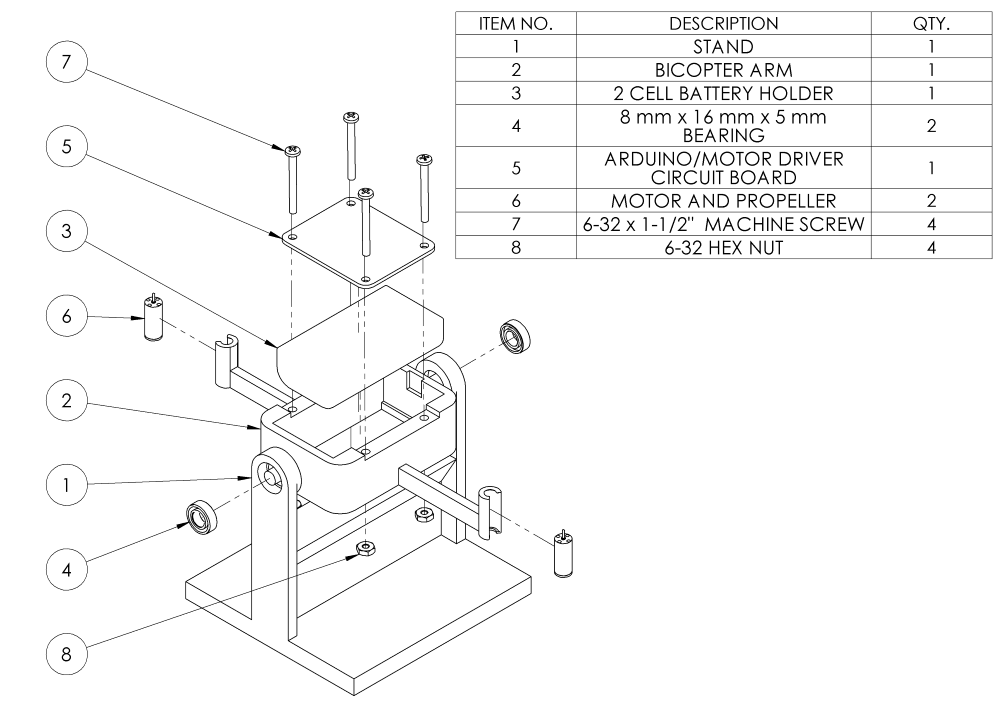

## Task 2: Preparation

Download the Simulink model **"bicopter_external.slx",** and navigate to hardware settings.

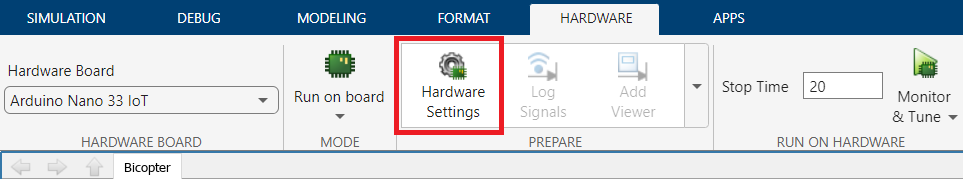

Under the settings, navigate to **Wi-Fi Properties** and enter your network credentials. If your network requires additional authentication, consider using a different network, or a personal hotspot. Ensure that your computer is connected to the same network.

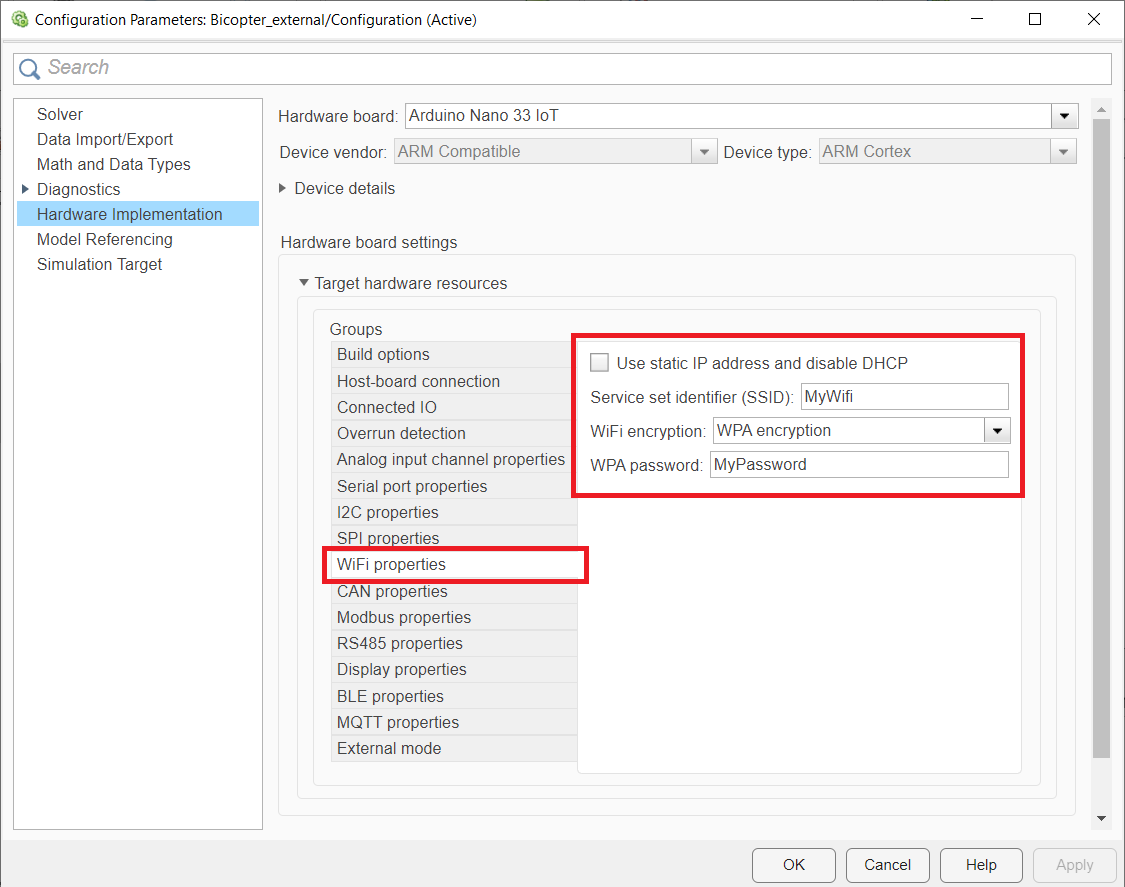

With the Arduino connected to your computer via USB, click **Build, Deploy & Start** under the **Hardware** tab.

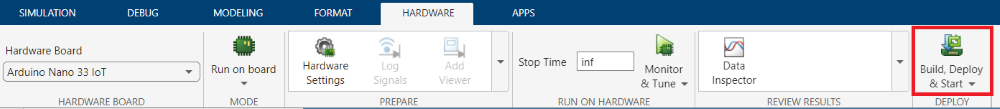

Next turn the motor driver on, and disconnect the USB cable. After programming, locate the IP address of the Arduino in the output displayed in the **Diagnostic Viewer**.

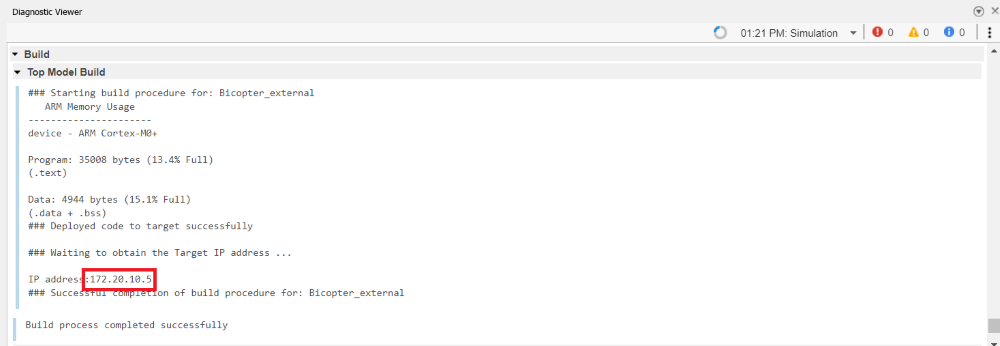

In the following code, replace `'172.20.10.5' `with your Arduino's local IP address, then run this section.

clear
close all
tcp = tcpclient('172.20.10.5',25000);

## Task 3: Open Loop Control

The next step in the project is to measure the response of the bicopter to input data. The input data can be gererated using the MATLAB funciton idinput as follows:

dur=2000; % number of data points
Input = idinput(dur, 'rbs', [0 1/10], [-10 10]);

This generates a binary input with a frequency bandwidth from 0 to 0.1 of the Nyquist frequency and a range from -10 to 10. Then, the input is sent to the Arduino and the resonse of the Bicopter is recorded:

write(tcp,0,"int8");
pause(1);
write(tcp,Input,'int8');
flush(tcp);
tic
en = 0;
while en == 0
    dat = read(tcp,2,'double');
    en = dat(2);
end
D = read(tcp,2*dur,'double');
Output = D(1:2:end);
en = D(2:2:end);
T_f = toc;
clear tcp

Next we will save the data as an `iddata` structure.

ts = 0.01;
data = iddata(Output',Input,'Ts',ts);
plot(data)

## Task 4: System Identification

Once the data is collected in `tfdata `format, the input-output data can be used to fit a model to the system. The following command fits a transfer function with 4 poles and 3 zeros to the data. 

G = tfest(data,4,3,'Ts',ts)
compare(data,G)

## Task 5: Controller Design and Implementation

After fitting a model to the bicopter i/o data, we proceed with the design of a controller. The following uses the built-in `pidtune` command to design a PID controller. 

C0 = pid(1,1,1,'Ts',ts,'IFormula','BackwardEuler','DFormula','BackwardEuler');
C = pidtune(G,C0)

## Task 6

Once you have designed a controller for the bicopter, the next step is to implement it onto the Arduino. Download and open the "bicopter_controller.slx" Simulink model. Replace the PID block with your controller/specifications. The TCP status signal is used as  reset trigger so that the controller starts from zero initial conditions when data is sent. Once you have implimented your controller onto the Simulink model, follow the same steps as **Task 2** (connect USB cable, set COM pots, and define your Wi-Fi network settings).  and then program the board using **Build, Deploy & Star**t button. Remove USB cable and turn the power switch to **ON**.   Once again, connect to the Arduino TCP server using:

tcp = tcpclient('192.168.51.234',25000)

tcp =   tcpclient with properties:

              Address: '192.168.51.234'
                 Port: 25000
    NumBytesAvailable: 0

  Show all properties, functions


replacing `'172.20.10.5'` with your device's IP address.

Next, we can define an input array, which is the desired angle of the close-loop control. As an example, I have defined:

dur = 2500;
% Generate setpoint signal
Input = zeros(dur,1);
 Input(501:1000) = 0.3;
 Input(1501:2000) = -0.3;

With this, I can connect to the Arduino, send the input values, and record the response:

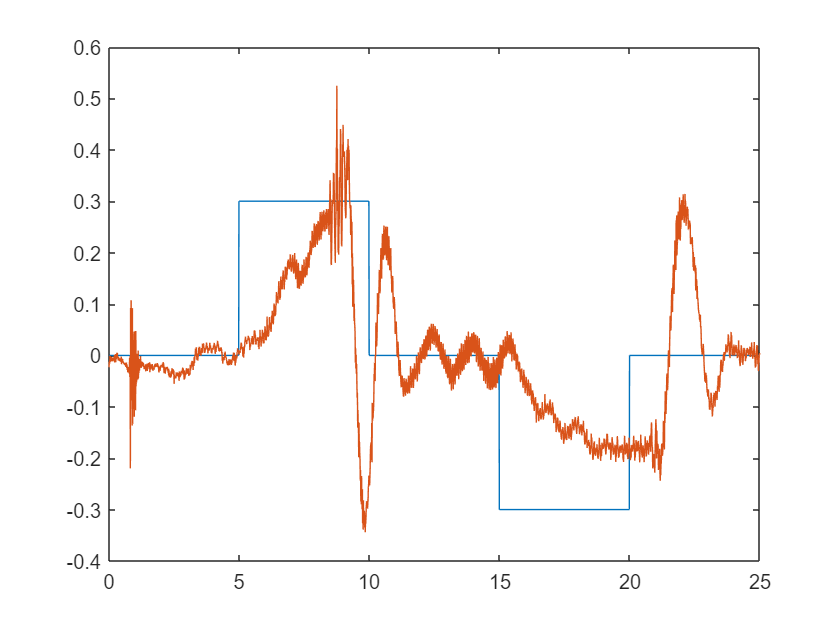

write(tcp,0,'single');
pause(0.5);
flush(tcp);
write(tcp,Input,'single');
tic
en = 0;
while en == 0
    dat = read(tcp,4,'double');
    en = dat(4);
end
D = read(tcp,4*dur,'double');
Output = D(1:4:end);
Control = D(2:4:end);
SP = D(3:4:end);
en = D(4:4:end);
T_f = toc;
clear tcp

figure
Time = 0:0.01:0.01*(dur-1);
plot(Time, SP);
hold on
plot(Time, Output);

lsim(feedback(C*G,1),SP,Time);

Unrecognized function or variable 'C'.

legend('Desired Angle','Measured Angle','Simulated Response')

## Further Studies:

- Change the input used for system identification and try to optimize the bandwith and amplitude to provide the best fit

- After collecting data, try fitting different models, such as higher order transfer functions, ARX models, n4sid, etc.

- Design controllers using different methods and experiment with implimenting onto the bicopter